# Supervised Learning (let's teach a machine to build some models to explain our data)

[Return to introduction](matlab: edit S1_Introduction.mlx)

In this section, we will utilize MATLAB® applications to try out two types of [supervised learning](https://en.wikipedia.org/wiki/Supervised_learning): classification and regression learning. You should go through the [unsupervised learning script](matlab: edit S2_Unsupervised_learning.mlx) before proceeding, as it introduces the dataset we are using here. If the data is no longer in your workspace, the following code will get everything set up: 

load ovarian_dataset.mat
ovarianTargets = ovarianTargets'; 
ovarianInputs = ovarianInputs'; 

## Classification learning 

One form of supervised learning is [classification](https://en.wikipedia.org/wiki/Statistical_classification) learning, in which we feed the data (`ovarianInputs)` to the computer, but we also give the computer the answer (the diagnosis, in this case). The machine can learn from this information how the inputs map to the diagnosis and will build a model to describe this transformation. The ultimate goal is to be able to collect new patient data (new blood serum samples), give this data to the model, and have the model tell us whether this patient is likely to have cancer or not. 

### 1: Get started with the app

Let's try this out! Luckily, there is a handy app for classification learning. Because we want to give MATLAB *all* of the data including the outcome, let's make a new table with the outcome in it. As we discussed in the previous script, we only need one column of ovarianTargets, because the columns contain redundant information. 

ovTable = [ovarianInputs ovarianTargets(:,1)];

`ovarianInputs` had 100 columns, with each column containing information about a different protein marker (each row is a patient). Here, we've added the patient diagnosis as an additional column at the end, column 101. 

1- In the **Apps** tab, open up 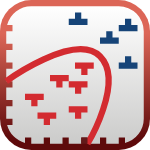 **Classification Learner**.  

2- Once in the app, start a 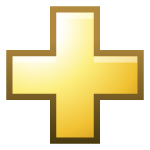**new session**, and select variables **from workspace**. 

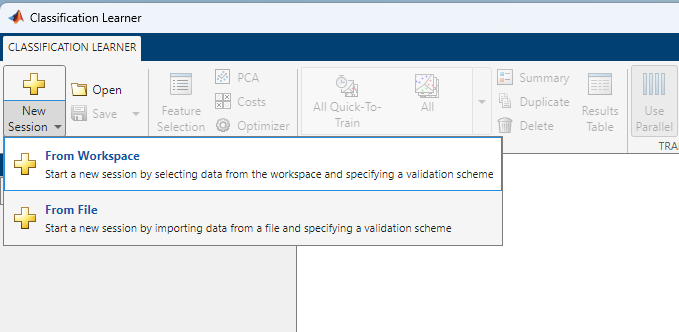

3- Select `ovTable` as your **data set variable.**

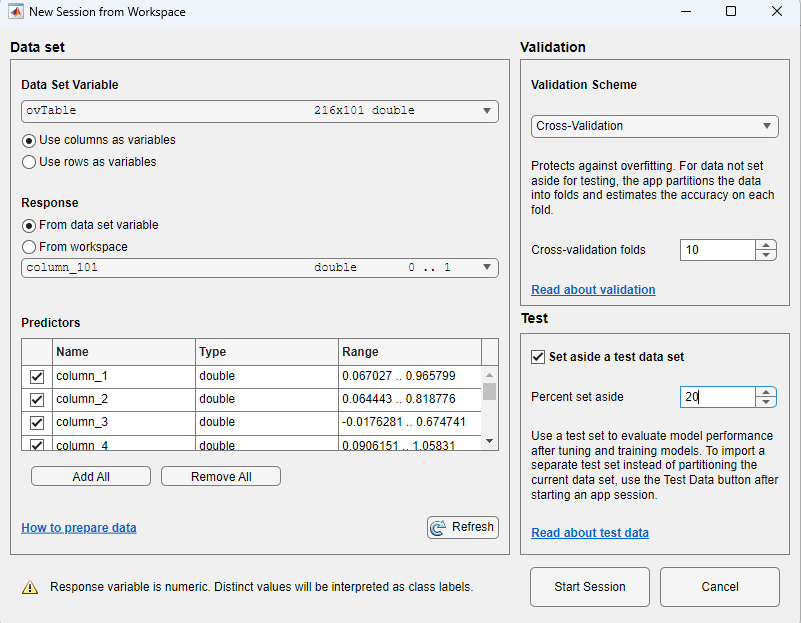

4- The **response **means the outcome, in this case, the diagnosis. The diagnosis is now the last column of `ovTable`, so make sure the response is set to `column_101`. 

5- Next, let's look at the **validation** and **test** boxes on the right. The classification learner app will partition data into testing and validation sets, and then its accuracy will be determined by how it performs in the validation stages. 

Cross-validation is a good way to make sure your data fit is generalizable and not too perfectly fit to the points you input in the training set. If it's overfitting, when you feed the model new data, it probably will not be able to make generalizations and therefore won't perform very well. Cross-validation will partition the data into the number of "folds", or groups you specify, and then it will run several times choosing different folds as "training" and "model validation" groups on each run. This way, different combinations of data are used on each run during training. You can keep the number of folds at 5, or play around with this number and see how it affects your models. I've set it to 10 here.

6- It's also good to **set aside a test set** of your data that is not used by the model at all during training so that you can test out if your model is working! I've set aside 20% here. 

7- Click **start session**. 

### 2: Train a model

Now your data is all loaded into the session and it's time to choose the model you want to train. There are a lot of different types of models for classification learning. MATLAB has an option to let you select your model specifically, but you can also just click an option like** All Quick-To-Train** and several different models that may work for your data will be selected for you. You can then train these models and compare the accuracy of each. 

1- Let's try that here.  Select 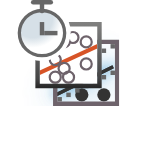**All Quick-To-Train **and then 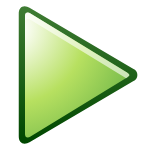**Train All**. 

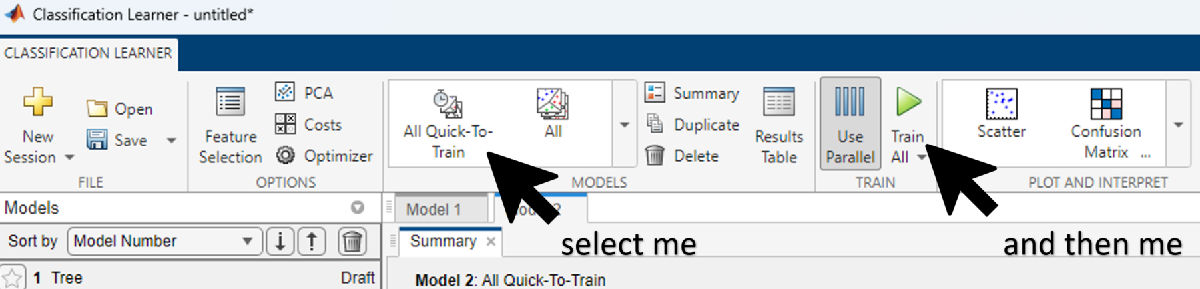

It will take a little bit of time for the models to train. The best model in my case was the Efficient SVM model ([support vector machine models](https://en.wikipedia.org/wiki/Support_vector_machine), SVM for short, work by finding the planes the computer can draw through the multidimensional data axes that best separate the data).  

2- Click on the best model (the model with the highest validation accuracy) and then you can play around with visualizing how the model works. Select 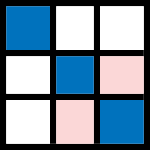 **Confusion Matrix** to see a heatmap of how well the algorithm performed. The [confusion matrix](https://en.wikipedia.org/wiki/Confusion_matrix) shows the actual diagnosis on the y-axis, with the predicted diagnosis, or class, on the x-axis. In our case, the model did a pretty good job in the validation stages: Most patients without cancer ("0") were classified as such, and most patients with cancer ("1") were classified as such. Our model was not very "confused"! 

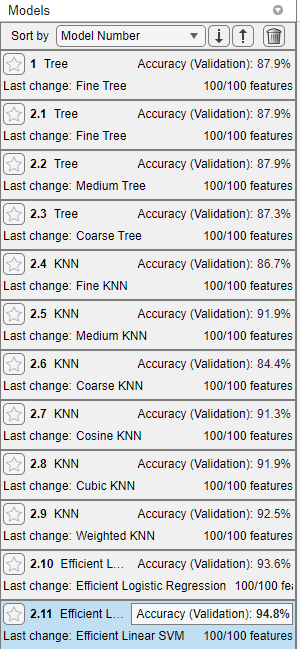      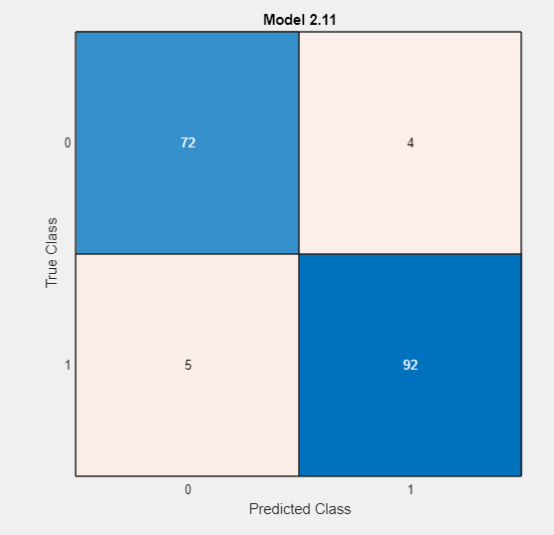

For our purposes, we don't need to fully understand what all of these models are right now, but you can learn a lot more about what these model types mean and how to use them in the [Machine Learning Onramp](https://matlabacademy.mathworks.com/R2023a/portal.html?course=machinelearning) or by looking at [this documentation](https://www.mathworks.com/help/stats/choose-a-classifier.html) for the classification learner application that describes available models. 

### 3: Test the model

We know how the model performs in the validation stages (recall that validation involves retesting the same data, just partitioned in different ways). We also set aside 20% of our data at the beginning, and the model has not seen any of this data yet. Let's try testing that 20% of the data. Our question here, in the testing stage, is: How does the model perform on data it has never seen in its life? 

1- Because we've already set aside the test data, we can select  **Test All** and the test data will be fed through all 11 of our models here. Depending on your version of MATLAB, you may just be able to select  **Test All **as shown below, or you may need to go into a "Test" tab at the top of the window, before  selecting **Test All. **

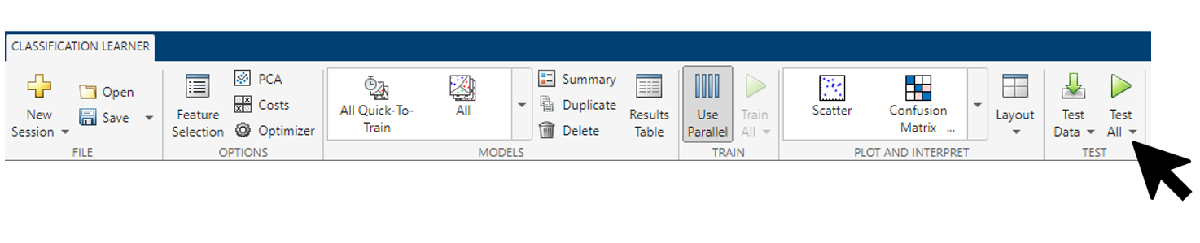

2- Select 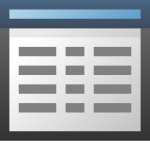 **Results table** at the top to see how each model performed, both during training and testing. 

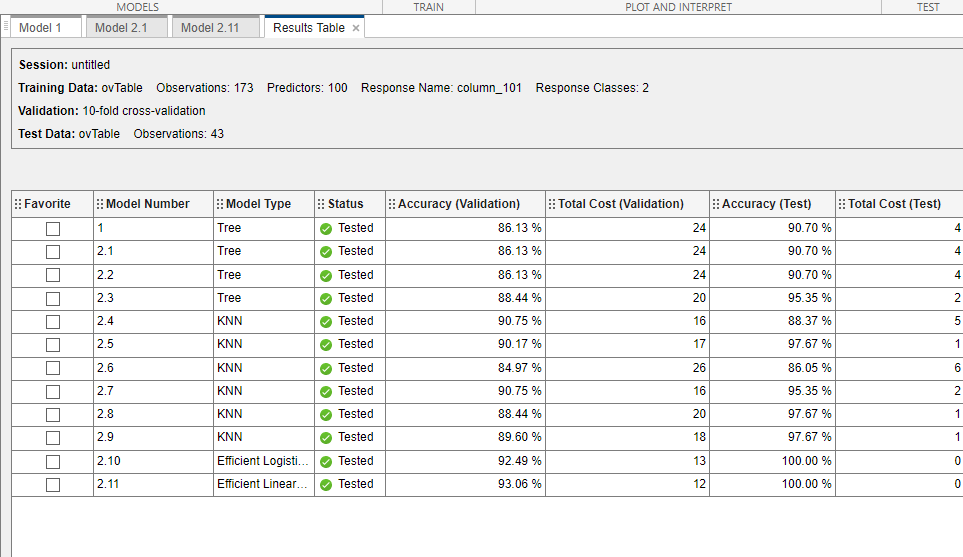

In this case, some of our models got 100% correct in the testing phase! A+ for them. 

You're bound to get different results as you run this with different parameters or even rerun it with the same parameters, as different training and testing data will randomly be assigned each time. 

3- If you want to save this model for later use, **favorite** the models you want to export by clicking the check box next to the model number. Then, select 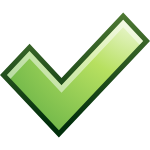**Export Model**,  and 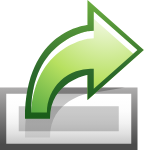 exporting it to the workspace. Now you can use your trained model on new data!

### 4: Improve the model

Let's go over a few extra options here to improve your models! The Efficient Linear SVM worked pretty well, but let's see if we can make it better by changing some of the model training parameters.

One thing that sometimes helps improve models is to reduce the number of features you are training the model on. In this case, we have 100 proteins in the dataset, but are all of them productive or helpful to the model? Some might be redundant and make the model more complicated for no reason. We can use *feature transformation* (you've already heard about one form of this -- PCA!) or* feature selection*, where we just select the best or most predictive features and only train the model on those. Both of these are possible in the app. 

Let's try feature selection first.  

#### 4a- Feature selection

1- First, let's set up a new (untrained) model template. Navigate to the models dropdown (you may need to return to the Learn tab) and locate the **Efficient Linear SVM** under the "Efficiently Trained Linear Classifiers" header. 

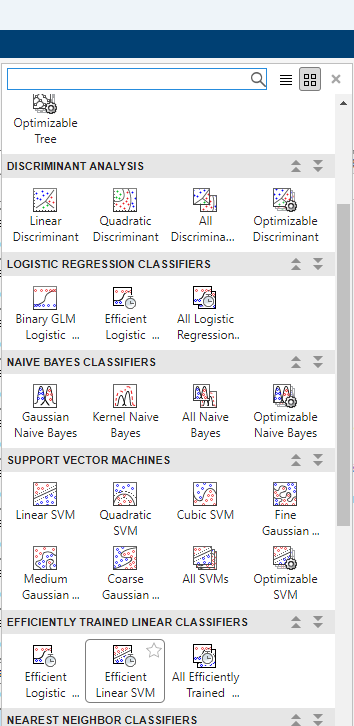

A new model called "Model 3" will populate in your model's pane. We can see that both model 2.11 and model 3 are Efficient Linear SVM models: 

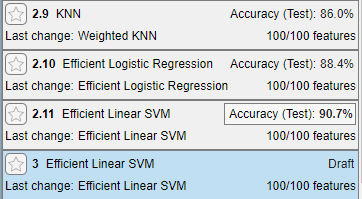

2- With model 3 (new model template) highlighted, click  **Feature Selection **

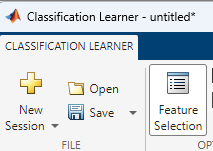

3- We need to select a **Feature Ranking Algorithm**, like [chi-squared](https://en.wikipedia.org/wiki/Chi-squared_test), which ranks the features in terms of their importance for prediction. Select **Chi2.** 

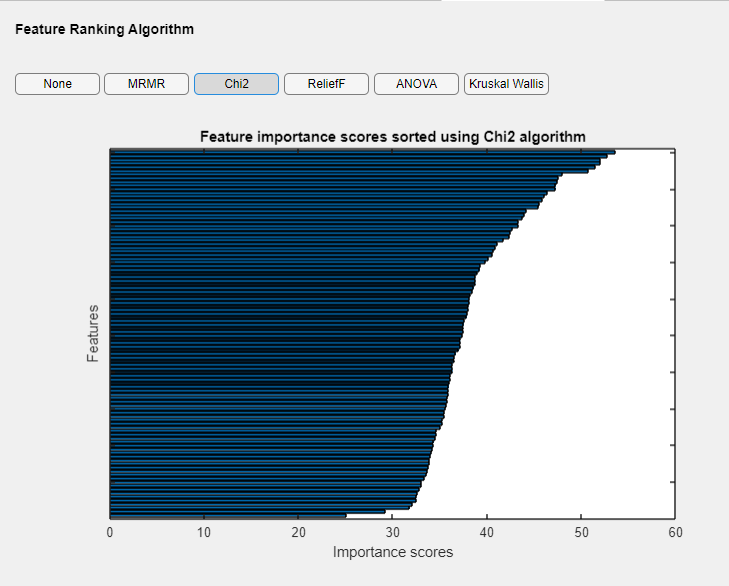

You can see the rankings of all the features, and determine how many you want to keep. The "importance scores" drop off relatively quickly here, so let's try 20 features.

4- Type "20" in **Num features to keep**. Select **Save and Apply**. 

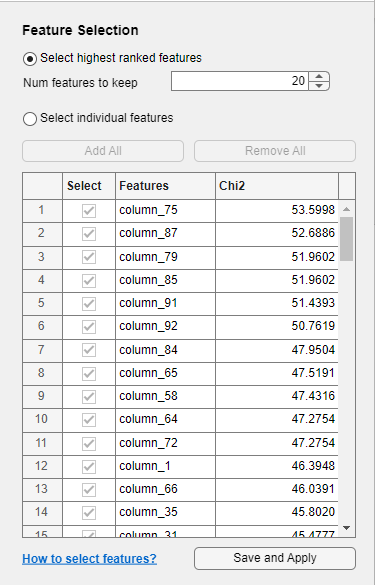

5-Then select **Train All** to train your new model. 

You can see how the accuracy changes with fewer predictors! In this case, it does drop (lower accuracy and more patients are misclassified into both categories), but the model is faster! 

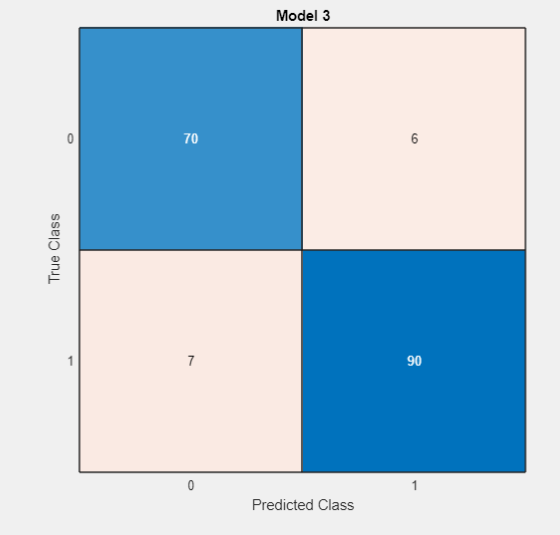

In the case of patient diagnosis, you probably would want to choose accuracy over speed. This is often a tradeoff to keep in mind. 

#### 4b- Feature transformation (back to PCA!)

Now let's try out feature transformation. 

1- Make a new Efficient Linear SVM model. Navigate to the models dropdown again and locate the **Efficient Linear SVM** under the "Efficiently Trained Linear Classifiers" header. Now you should see a new model draft in your models pane. Notice that it says 20/100 features under "Draft", which means the feature selection from step 4a carried over into our draft model. Let's revert that. 

2- Return the feature selection to all features by going into  **Feature Selection** and changing the **number of features to keep** from 20 back to 100. **Save and apply**.  

3- Click **PCA** (the button is located next to the feature selection button). 

4- In the PCA popup window, check **Enable PCA**. You get to tell MATLAB how much of the explained variance you want to include (this will determine the number of principal components used). Let's stick with 95%.

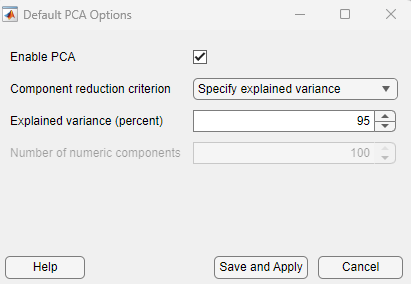

5- Select **Save and apply. **

6- Select **Train All** to train this model. What changes? 

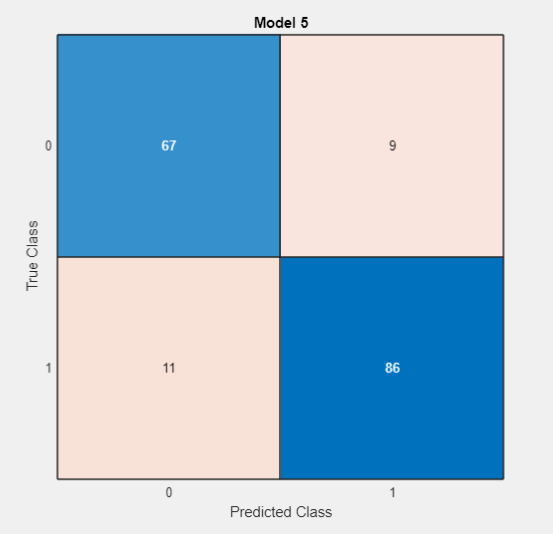

7- We can also test this new model with the data we saved at the beginning. Select **Test All**. 

 How do your feature-selected and feature-transformed models perform in the testing stage? 

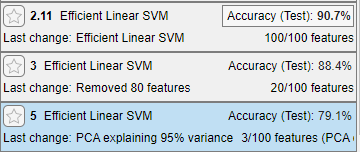

In my case, Model 3 is the feature-selected model and Model 5 is the feature-transformed model. Yours may be numbered slightly differently or look slightly different! 

  Play around with increasing explained variance, or changing the feature ranking algorithms, and see what model and features work the best. Make sure to make a new model draft each time. 

#### 4c - Model costs

 Something to consider is what we care about getting from this model *the most*. In this case, we want all patients who have cancer to be identified as having cancer. If we tell a patient who has cancer that they probably don't, that's a big and extremely costly mistake. If we tell a patient who doesn't have cancer that they might, they'll go for more testing and eventually be told that they don't have cancer. This is still a mistake--it stinks for the patient--but it's not nearly as bad as the first type of mistake. Therefore, we would rather have 0 [false negatives and a few false positives](https://en.wikipedia.org/wiki/False_positives_and_false_negatives) in this model. 

We can change the "cost" of mistakes in our model to reflect this. 

1- First, make a new model draft. Navigate to the models dropdown again and locate the **Efficient Linear SVM** under the "Efficiently Trained Linear Classifiers" header. Now you should see a new model draft in your models pane. You'll notice that this model draft says "using PCA", so we'll have to turn the PCA back off. 

2- Select **PCA** again. Unclick **Enable PCA**. **Save and Apply**. 

3- Underneath the **PCA** button, select **Costs**. Having cancer is category "1" and a non-cancer diagnosis is "0". We want to minimize the number of people who are told they don't have cancer (predicted class 0) but have cancer (true class 1) to be minimized (the number of false negatives), so we can double the cost of category 1 being predicted as category 0: 

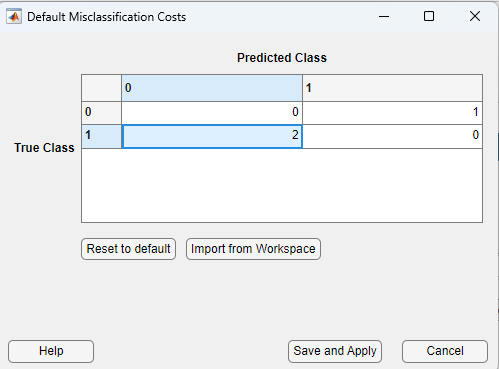

4- **Save and Apply**. 

Your model's cost matrix will appear as "custom". 

5- Select **Train All** to train the new model.

 How did the confusion matrix for this model change compared to the first Efficient Linear SVM model with 100 features (Model 2.11)?  You can ask to be shown the true positive and false negative rates in the confusion matrix pane so that you can visualize this a bit more easily. 

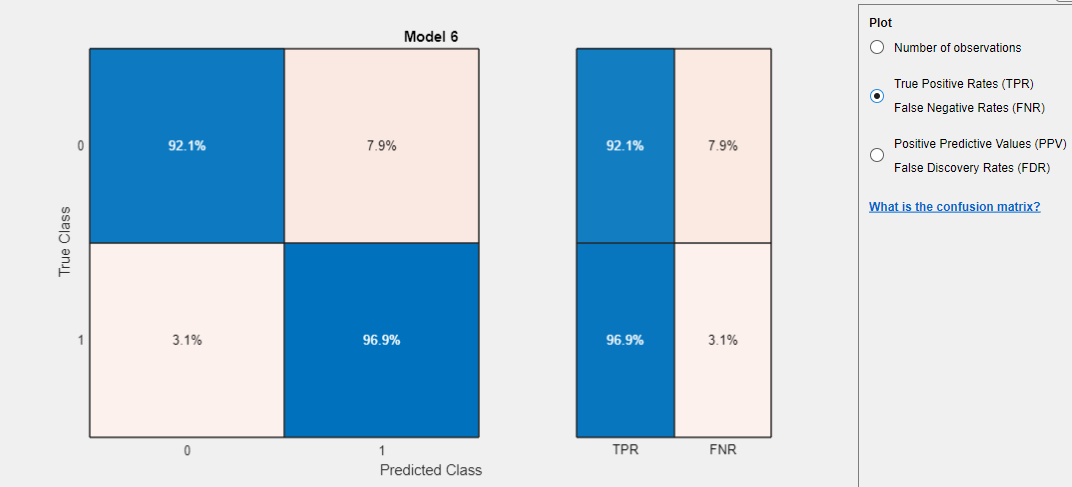

  What if you try different cost values like 3 for the false negatives?

When you're done testing new models, close the Classification Learner app. 

### 5: Further Resources

The classification learner has a lot of easily adjustable functionality, and you can test a ton of different models at once, so its worth using! 

However, you can of course also write code yourself to do this type of machine learning. Again, to learn more about how to do this and about all the different model types and what they do, the [MATLAB training course](https://matlabacademy.mathworks.com/R2023a/portal.html?course=machinelearning) on machine learning is extremely helpful (also, this [related reference](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlml&language=en&release=R2023a)). 

## Regression learning

Sometimes you might not want to train a machine to classify data into certain groups, but rather to make predictions for you ([regression](https://en.wikipedia.org/wiki/Regression_analysis) learning). This usually happens when you have continuous variables-- for example, blood pressure, weight, age, and cholesterol levels-- and want to use this information to predict something-- like an individual's risk for heart attack. This is still supervised learning-- so you are training the machine on the variables (blood pressure, etc.) and the answer (did the patient have a heart attack), and then the machine will create an internal model such that if you give it information about new patients, it can predict their risk of a heart attack on a continuous scale. 

### 1: Switch things up--mollusk data

Let's change things up a little bit and use a dataset about abalone from [UCI's Machine Learning Repository](http://archive.ics.uci.edu/) [1]. Abalone are mollusks and they are cool because much like trees, you can use the number of rings on their shells to determine how old they are! 

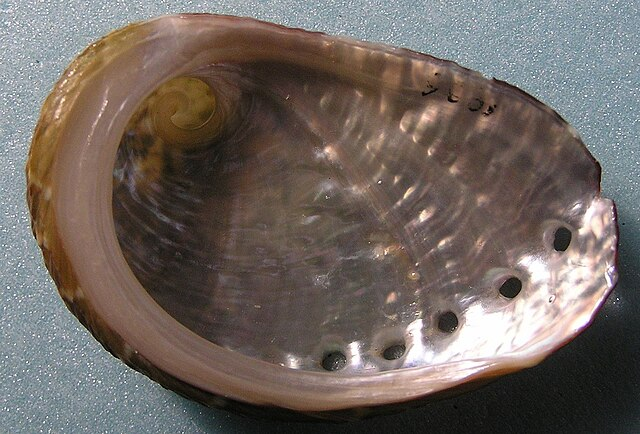

[Haliotis rugosa pustulata](https://commons.wikimedia.org/wiki/File:Haliotis_rugosa_pustulata_002.jpg), a sub-species of abalone typically found in Japanese coastal waters

Given a bunch of continuous variable information about abalone, like their length and weights, can we predict the number of rings they have, and thereby their age? Predicting abalone age in a population can give biologists a lot of information about the population dynamics in a given ecosystem! 

Let's set up our data. This dataset also comes with MATLAB, so all you need to do is load it. 

load abalone_dataset.mat
abaloneInputs = abaloneInputs'; 
abaloneTargets = abaloneTargets'; 

This dataset contains information about 4177 abalone! The variable `abaloneInputs` now contains columns with measurements of 8 different attributes of these creature's shells. The number of rings on each shell is contained in `abaloneTargets`. 

  Type and run `help abalone_dataset` to learn more about the dataset and which attributes are measured: 

We want to predict abalone age (in years!), which can be calculated by adding 1.5 to the number of rings (see information in `help abalone_dataset` above).

So let's change our Targets array to contain age information instead: 

abaloneAge = abaloneTargets+1.5

As we did before,  we will also concatenate all of our data into one variable so it is more easily fed into the Regression Learner app: 

abaloneTable = [abaloneInputs, abaloneAge];

### 2: Use the Regression Learner App

1- In **Apps**, open the 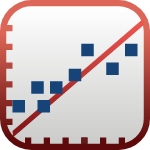 **Regression Learner **app. 

2- Start a  **New Session** (from the workspace).

3- Select `abaloneTable` as the **Data Set Variable**. Since we added the `abaloneAge` as the last column, choose the last column (column 9) as the **response** (what we want to predict). Let's use the same cross-validation (10) and test set values (20%) as we did before in the classification section. **Start Session**. 

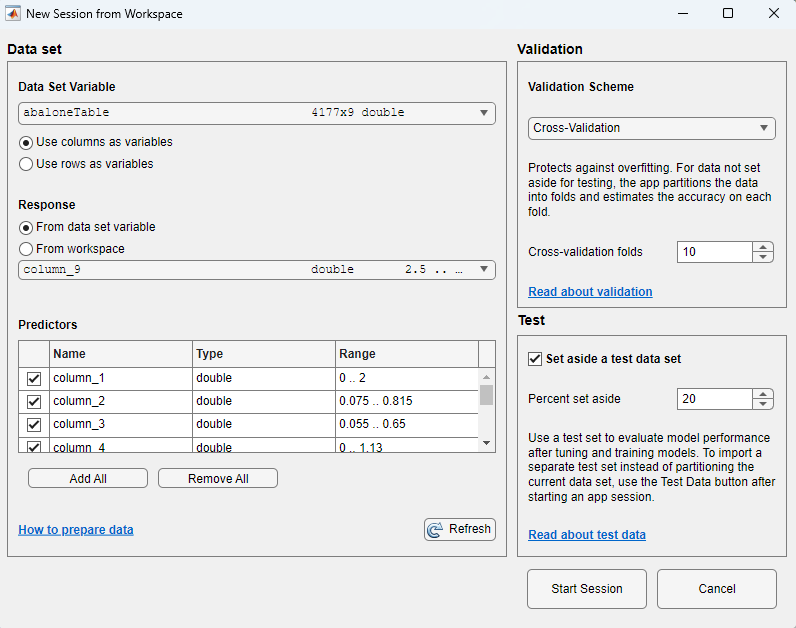

You'll notice that this app has very similar options and setup to the Classification Learner. The main difference here is we will be utilizing regression models instead of classification models. Again, it helps to train several models. 

4- Select **All Quick-To-Train **and then **Train All**. 

A few models are trained. You'll notice that rather than % accuracy of prediction, you'll get a value called RMSE, the [root mean squared error](https://en.wikipedia.org/wiki/Root-mean-square_deviation). This tells you how different your model is from the data. In the case of a linear regression with just two predictors (a straight line), you are getting information about how far from that predicted line your data lie. The model with the *lowest RMSE *will be the best predictor of the data. 

5- Select  **Results table** to see how each model performed in the training stages. You'll see the RSME for each model here, as well as the [R-squared value](https://en.wikipedia.org/wiki/Coefficient_of_determination), which we discussed in the biosciences statistics module***(add link to module 2 File Exchange)***. The higher the R-squared, the better your model. 

In my case, a [simple linear regression model](https://en.wikipedia.org/wiki/Simple_linear_regression) (the trend line or line of best fit), performed the best.

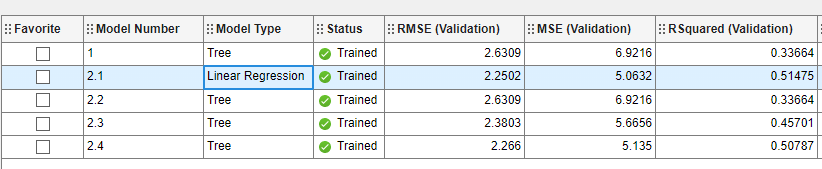

6- Select  **Test All **to test the data we withheld when we started the session (20%). In some versions of MATLAB, you will need to go into the "Test" tab at the top of the window to find this button. 

 How does the model that performed best during training perform in the testing stage? 

7- Select **Predicted vs. Actual (test). **It can be helpful to look at the "predicted versus actual" graph for both the validation and test runs of the model. This can help give you some intuition as to how well your model can predict the abalone age from height and weight information. 

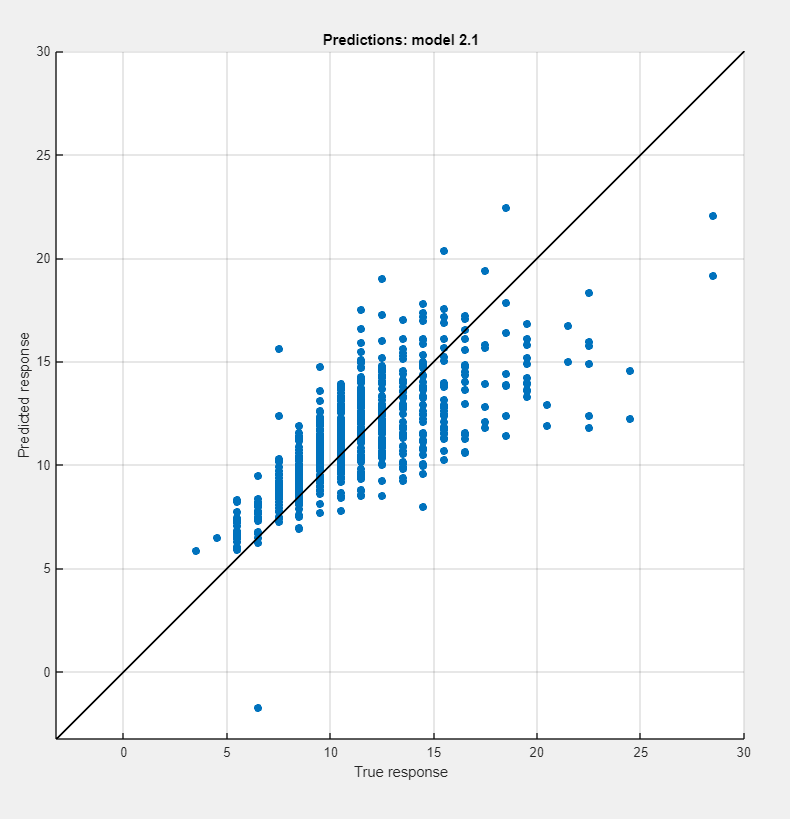

  As with the classification learner, you can play around with applying PCA  before training your model, or playing around with the number of features (predictors) used and see how this changes your prediction errors and overall model performance. 

When you're done playing around with these regression models, close the Regression Learner app window. 

You've learned how to apply several machine learning algorithms, both supervised and unsupervised, to biological data. These methods can allow you to create models that can help you predict whether or not a patient has a disease, let you estimate the ages of a sea creature population, and much much more. 

We've learned how to group data using unsupervised learning and how supervised learning can be used to make classifications and predictions. MATLAB's classification and regression learner applications are easy ways to implement machine learning algorithms! 

If you want to learn more about machine learning and how to choose models, check out the [Machine Learning Onramp](https://matlabacademy.mathworks.com/R2023a/portal.html?course=machinelearning) (and this [related reference](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlml&language=en&release=R2023a)). 

Next, we'll put these techniques into practice with a problem set. 

## References 

[1] Murphy,P.M., Aha, D.W. (1994). UCI Repository of machine learning databases [http://www.ics.uci.edu/~mlearn/MLRepository.html]. Irvine, CA: University of California,  Department of Information and Computer Science.

[Continue to next section (Problem set)](matlab: edit S4_Problem_set.mlx)

[Return to introduction](matlab: edit S1_Introduction.mlx)